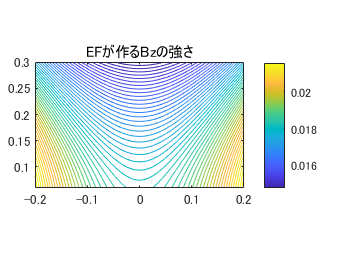

%grid
n=101;
zmax=0.2;
zmin=-0.2;
rmax=0.3;
rmin=0.06;
[zq,rq]=meshgrid(linspace(zmin,zmax,n),linspace(rmin,rmax,n));

grid2D=struct('zq',zq,'rq',rq);
clear zq rq

EF=150;
r_EF   = 0.5 ;
n_EF   = 234. ;
i_EF    =EF;
z_EF   = [-0.68;   0.68];
Br_on =true;
[Bz_EF,Br_EF] = B_EF(z_EF(1),z_EF(2),r_EF,i_EF,n_EF,grid2D.rq,grid2D.zq,Br_on);
contour(grid2D.zq(1,:),grid2D.rq(:,1),squeeze(Bz_EF),50)
colorbar
axis image
axis tight manual
title('EFが作るBzの強さ')

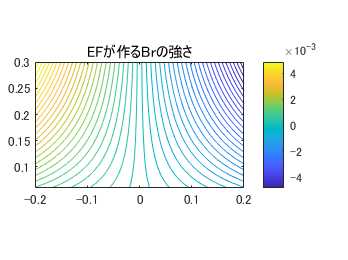

contour(grid2D.zq(1,:),grid2D.rq(:,1),squeeze(Br_EF),50)
colorbar
axis image
axis tight manual
title('EFが作るBrの強さ')

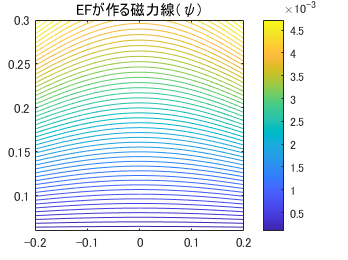

figure
contour(grid2D.zq(1,:),grid2D.rq(:,1),cumtrapz(grid2D.rq(:,1),Bz_EF,1),50)
colorbar
title('EFが作る磁力線（ψ）')

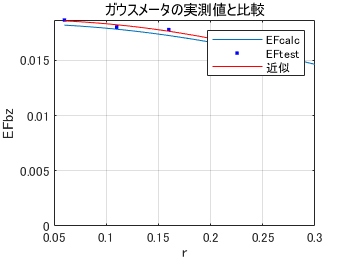

EF_real=[6,11,16,28;18.650000000000000,18.010000000000000,17.780000000000000,15.210000000000000];
r=EF_real(1,:)/100;
EFbz=EF_real(2,:)/1000;
figure
plot(grid2D.rq(:,1),Bz_EF(:,51),'-','DisplayName','計算値')
hold on
[xData, yData] = prepareCurveData( r, EFbz );

% 近似タイプとオプションを設定します。
ft = fittype( 'poly2' );

% モデルをデータに近似します。
[fitresult, gof] = fit( xData, yData, ft );

% データの近似をプロットします。
plot( fitresult, xData, yData );
legend('EFcalc','EFtest', '近似 ', 'Location', 'NorthEast', 'Interpreter', 'none' );
% ラベル Axes
xlabel( 'r', 'Interpreter', 'none' );
ylabel( 'EFbz', 'Interpreter', 'none' );
grid on
ylim([0 inf])
legend
hold off
title('ガウスメータの実測値と比較')